## Introduction

A testbed was developed to spectrally reproduce display stimuli for testing color calibration kits. The testbed, LightSim, consists of a tunable light source (TLS) for generating the target spectrum, an integrating sphere for diffusing the light for the color calibration sensor, computer hardware and software components for controlling the TLS, and a spectroradiometer for measuring the output spectrum. 

The testbed was treated as a 1-pixel, 1024-primary, 40,000-level display in contrast to the regular n-pixel, 3-primary, 256-level displays. The TLS used 1024 columns of a digital light processor (DLP) to selectively reflect the dispersed light coming from a xenon lamp after passing the grating. Each column was independently controlled by an integer value between 0 and 40,000 to form a bandpass filter with a bandwidth of 25 nm at a spectral resolution of 0.40 nm. The spectroradiometer measured the output spectrum between 380 nm and 780 nm at 1 nm resolution.

The final forward model accepts a vector of 1024 column values and predicts the output spectrum of 401 wavelengths.

To simulate the stimuli of a given display, the TLS model needed to be inversed by solving the 1024x401 matrix equation with the R General Purpose Optimization tool (optim L-BFGS-B). The inverse model accepts a target spectrum and then calculates the 1024 column values.

## Setup

Controlling OL490/HIMS1 and PR730 in WO62/3143


[ret hname] = system('hostname');
if isequal(hname(1:end-1),'wcc-FX')
    HIMS = 1;
else
    HIMS = 2;
end
HIMS

HIMS = 2


CHARACTERIZING = 0

CHARACTERIZING = 0


ols = OL490Sim(HIMS)

ols =   OL490Sim with properties:

             col_spec: []
             HIMS_VER: 'HIMS2_07032022'
       spike_filename: 'spike_HIMS2_07032022.mat'
       gamma_filename: 'gamma_HIMS2_07032022.mat'
    col_spec_filename: 'col_spec_HIMS2_07032022.mat'
             speC_max: []
             speC_min: []
            reflC_min: []
            classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@OL490Sim'
        spikedatapath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@OL490Sim/spike_HIMS2_07032022.mat'
     col_specdatapath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_HIMS2_07032022.mat'
        gammadatapath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@OL490Sim/gamma_HIMS2_07032022.mat'



if CHARACTERIZING
    ol
    cs
    clf; ols.check_ol_cs(ol,cs)
end

## Collect gamma measurement data

Measure 0%, 10%,... 100% of the fully on output spectrum.

Use the area under the curve (i.e., total power, which should be proportional to luminance) to determine gamma.

In the characterization stage, 350 out of 1024 columns were measured to construct the look-up table of the spectral reflectance. To avoid the prolonged measurement time required by the spectroradiometer to collect a limited number of photons reflected by one column only, seven columns were activated simultaneously to generate eight spikes that were at least 50 nm apart without any cross-talking.

if CHARACTERIZING
    ols.FWD_stimulate_gamma (ol,cs)
end

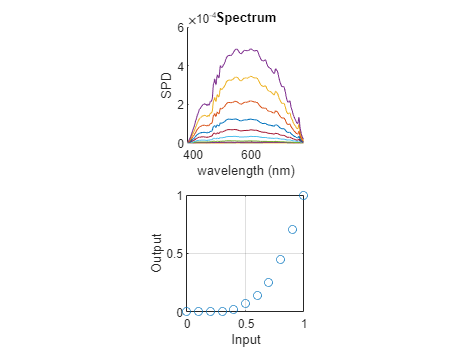

ols.FWD_stimulate_gamma_finding

## Collect spectral measurement data

if CHARACTERIZING
    ols.FWD_stimulate_spectrally (ol,cs)
end

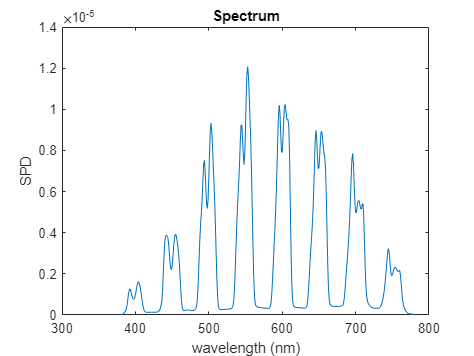

ols.FWD_stimulate_spectrally_finding

## Analyze spectral measurement data

ols.FWD_characterize_spectrally

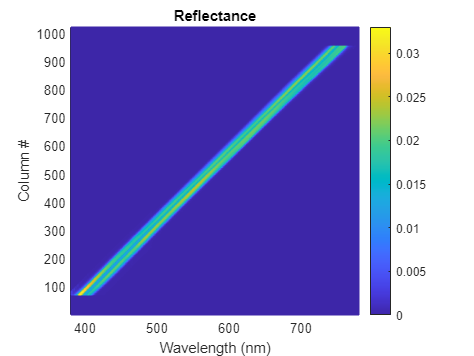

ols.FWD_characterize_spectrally_finding

## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

if CHARACTERIZING
    col_range  = [100:100:1000];

    vec = OL490Class.VEC_multiple_peaks(col_range);

    refl = ols.FWD_vec2reflC(vec);
    spec = ols.FWD_vec2spdC(vec);

    clf
    hold on
    spec.plot

    mea = ol.setColumn1024GammaandMeasure(vec,cs);
    mea.plot

    legend('Predicted','Measured')
end

## Check accuracy of the inverse model with 3 displays

Spectra of the red, green, and blue primaries of three displays were used to represent different color gamuts and lighting methods. A virtual reality device based on OLED (Oculus Rift), a professional-grade display based on CCFL-backlighting (NEC PA271), and a consumer-grade display based on LED-backlighting (HP Z24X) were measured to represent the DCI-P3, AdobeRGB, and sRGB color spaces. For each display, a model was created to accept the RGB input values and then predict the output spectrum.

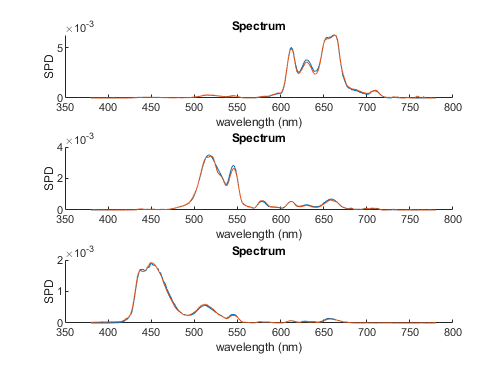

### NEC

disp_nec = NECPA271Sim(HIMS)

obj =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


disp_nec =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1.4220e-07 2.6829e-07 2.1158e-07 1.1358e-07 1.7134e-09 0 0 3.5114e-08 8.1161e-08 8.2006e-08 8.1559e-09 0 0 0 0 0 0 0 0 0 0 0 0 0 0 2.1556e-07 3.8862e-07 5.7258e-07 7.7394e-07 1.0139e-06 … ]
        spec_g: [0 0 0 0 0 0 0 0 0 0 0 0 8.2092e-08 1.4388e-07 1.5776e-07 1.4250e-07 1.0453e-07 4.5088e-08 0 0 0 0 0 0 4.5076e-08 9.7762e-08 1.1161e-07 1.0263e-07 6.8696e-08 0 0 0 0 0 0 0 2.3523e-08 1.5421e-07 1.7701e-07 1.7452e-07 1.5738e-07 … ]
        spec_b: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 2.9302e-08 1.2692e-07 2.8823e-07 4.6512e-07 6.4785e-07 7.8976e-07 8.4914e-07 9.4400e-07 1.1097e-06 1.4102e-06 1.9154e-06 2.5484e-06 3.3058e-06 4.1352e-06 4.9544e-06 5.9805e-06 … ]
     classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
      

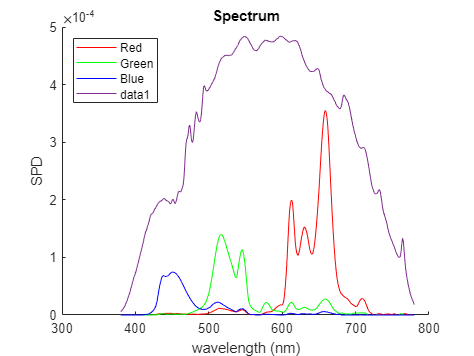

clf; check_RGB_primaries(ol,ols,cs,disp_nec)

if CHARACTERIZING
    disp_nec.OL490_model(ols)

    disp_nec.OL490_load_vec;

    compare_RGB_primaries(ol,ols,cs,disp_nec)
    movefile compare_RGB_primaries_result.mat compare_RGB_primaries_result_nec.mat
end

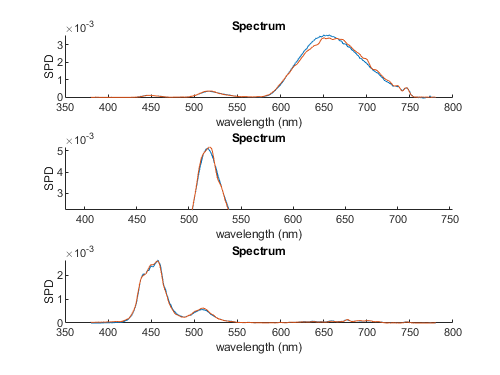

### HP

disp_hp = HPZ24xSim(HIMS)

obj =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


disp_hp =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1.0280e-07 3.1723e-07 3.1068e-07 2.4658e-07 1.5253e-07 9.0213e-08 9.8692e-08 1.1256e-07 1.2463e-07 1.1044e-07 5.3101e-08 0 0 0 8.2628e-08 1.9412e-07 2.8133e-07 2.7249e-07 8.5792e-08 0 0 0 0 0 … ]
        spec_g: [6.7486e-07 8.9482e-07 1.0829e-06 1.2209e-06 1.2861e-06 1.1596e-06 8.5463e-07 5.1837e-07 2.0097e-07 6.6422e-08 1.3524e-07 2.4007e-07 3.4052e-07 3.0197e-07 9.7880e-08 0 0 0 0 0 1.7811e-07 2.7683e-07 2.4157e-07 1.7849e-07 1.0657e-07 … ]
        spec_b: [0 0 0 0 0 0 1.0842e-07 2.6612e-07 4.0128e-07 4.2439e-07 3.2755e-07 2.0976e-07 9.7761e-08 7.0264e-08 1.4638e-07 2.4559e-07 3.5110e-07 4.2811e-07 4.6006e-07 4.7073e-07 4.5936e-07 3.9726e-07 2.7942e-07 1.7423e-07 1.0745e-07 1.7213e-07 … ]
     classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
   

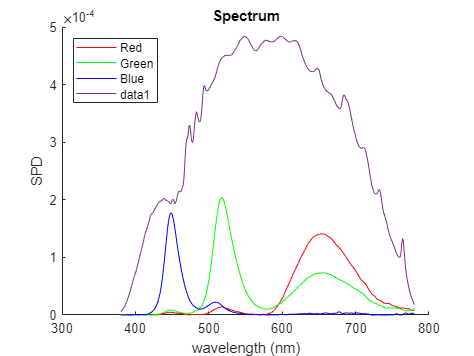

clf; check_RGB_primaries(ol,ols,cs,disp_hp)

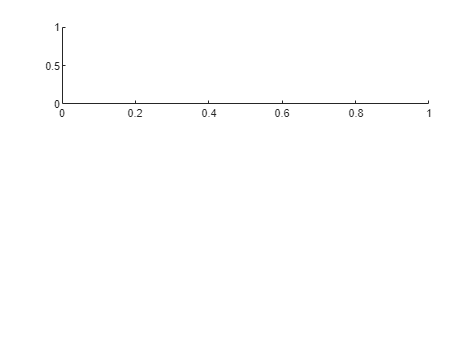

Dot indexing is not supported for variables of
this type.

Error in OL490Sim_test>compare_RGB_primaries (line 114)
mea_r = ol.setColumn1024GammaandMeasure(v,cs);

if CHARACTERIZING
    disp_hp.OL490_model(ols)
end
disp_hp.OL490_load_vec;

compare_RGB_primaries(ol,ols,cs,disp_hp)

movefile compare_RGB_primaries_result.mat compare_RGB_primaries_result_hp.mat

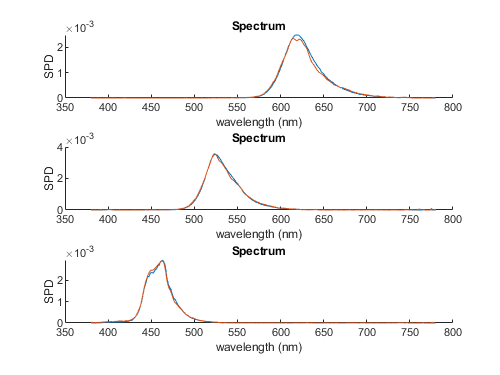

### Rift

disp_rift = RiftSim(HIMS)
clf; check_RGB_primaries(ol,ols,cs,disp_rift)


if CHARACTERIZING
    disp_rift.OL490_model(ols)
end
disp_rift.OL490_load_vec;
compare_RGB_primaries(ol,ols,cs,disp_rift)
movefile compare_RGB_primaries_result.mat compare_RGB_primaries_result_rift.mat

## ColorChecker Experiments

In the experiment, a color calibration sensor (DataColor Spyder X Elite) was tested with the 24 patches following the ColorChecker design. Each spectrum was simultaneously measured by the spectroradiometer (Konica-Minolta CS2000a) as the ground truth. The subject sensor allowed the user to select one of four backlighting modes (“White LED”, “Standard LED”, “General”, and “GB LED”) for improving the estimation. The test results were evaluated using the CIEDE2000 color difference metric. The experiment results show adequate linearity of luminance responses in the mid-range. Most color differences were less than 2.5 ΔE00, except for the darkest patch #24, indicating the limited capability of measuring dark shades. None of the four backlighting modes outperformed the others, and two blue patches #8 and #13 generated the most diverse results. This exercise demonstrated the utility of the LightSim for emulating arbitrary spectra without employing actual displays based on different backlighting methods.

return

s = ols.col_spec(500,:);
clf
plot(380:780,s,'LineWidth',2)
xlabel('Wavelength (nm)')
ylabel('SPD')
title('Column 500')

Try CIE D65

d65 = SpectrumClass.CIE_D(5000);
target_orig = d65.amplitude;

sc = 0.00002;
clf
hold on
ols.speC_max.plot
plot(380:780,target_orig*sc)

target = target_orig * sc;
vec = ols.INV_spd2vec(target);
vec_d50 = vec;

mea = ol.setColumn1024GammaandMeasure(vec,cs);
clf
hold on
plot(380:780,target)
mea.plot
mea.xyz

function check_RGB_primaries (ol,ols,cs,disp)
disp.show_spectra;
ols.speC_max.plot
end

function compare_RGB_primaries (ol,ols,cs,disp)

clf

subplot(3,1,1)
hold on
v = disp.vec_r;
s_predicted_r = ols.FWD_vec2spdC(v);
mea_r = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_r,'b:')
%s_predicted_r.plot
mea_r.plot
legend('Target','Measured')
legend('Location','west')

subplot(3,1,2)
hold on
v = disp.vec_g;
s_predicted_g = ols.FWD_vec2spdC(v);
mea_g = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_g,'b:')
%s_predicted_g.plot
mea_g.plot

subplot(3,1,3)
hold on
v = disp.vec_b;
s_predicted_b = ols.FWD_vec2spdC(v);
mea_b = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_b,'b:')
%s_predicted_b.plot
mea_b.plot

%
save('compare_RGB_primaries_result.mat','mea_r','mea_g','mea_b','s_predicted_r','s_predicted_g','s_predicted_b','disp')

end